## Numerical Integration

We can use the "Quadrature" to compute the integration for unary function

Function : $y\left(t\right)=cos\left(\frac{1}{a\text{ }t^2 }\right)$, when x was assigned within the range [0.2,   0.3], we need to compute its integration


$$G=\text{ }\int_{0\ldotp 2}^{0\ldotp 3} y\left(t\right)dt\text{ }=\text{ }\int_{0\ldotp 2}^{0\ldotp 3} cos\left(\frac{1}{a\text{ }t^2 }\right)dt$$


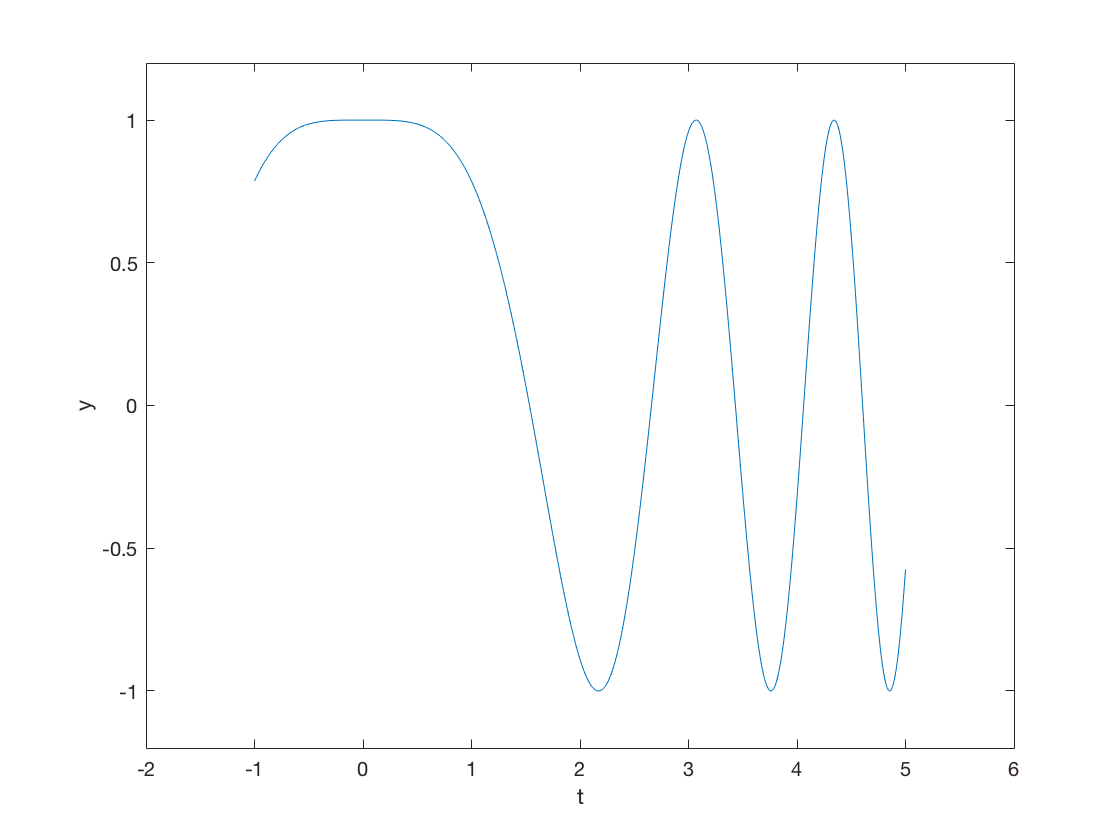

clear
clc

format long
a = 1.5;
func_handle_y = @(t)cos(1./a*t.^2);        % Assign the function handle

% Plot this function :
t = -1:0.01:5;
y = cos(1./a*t.^2);
plot(t, y)
axis([-2, 6, -1.2, 1.2])
xlabel('t');
ylabel('y');



num_integration_sum1 = quad(func_handle_y, 0.2, 0.3)

num_integration_sum1 =    0.099906239752516


inline_func_handle_y = inline('cos(1./a*t.^2)', 't', 'a');    % Assign the inline function handle
num_integration_sum2 = quad(inline_func_handle_y, 0.2, 0.3, [], [], a)

num_integration_sum2 =    0.099906239752516


## Compute the numerical integration for function $s=\text{ }\int_0^{\pi } \frac{sin\left(x\right)}{x}dx$

- Trapezoid algorithm :

clear
clc
format long 

x = linspace(0, pi, 100);    % Divide the integration range [0, pi] into 100 segments averagely.
x(1) = realmin;              % change the initial value to realmin, in order to avoid the NaN while dividing by zero.
y = sin(x)./x;
integration_value = trapz(x, y)

integration_value =    1.851910340309113


% Estimate the precision of trapzoid integration
t = linspace(0, pi, 200);    % Divide the integration range [0, pi] into 200 segments averagely
t(1) = realmin;
func_t = sin(t)./t;
integral = trapz(t, func_t)

integral =    1.851930441042991


error_estimation = abs(integration_value - integral)    % Estimate the error

error_estimation =      2.010073387825884e-05


- Simpson algorithm

y_simpson = @(x)(sin(x)./x);    % Function handle
simpson_integration_value = quad(y_simpson, 0, pi, 1e-7)

simpson_integration_value =    1.851937052680938


- Spline algorithm

spline_func = spline(x, y);    % Generate the spline function
spline_integral = fnint(spline_func);    % Compute the spline integration function
spline_integral_value = ppval(spline_integral, [0, pi]);
final_integral_value = spline_integral_value(2) - spline_integral_value(1)

final_integral_value =    1.851937051827447


- Symbolic integration

syms x;
symbolic_integration_value = vpa(int(sin(x)/x, 0, pi))

$$symbolic\_integration\_value = 1.851937051982466170361053370158$$

% The error between spline integral and the symbolic integral
error = abs(final_integral_value - symbolic_integration_value)

$$error = 0.00000000015501900327606992200928629809523$$

# So in conclusion : the symbolic integration is much more precise than the normal numerical integration, but spline integration is the most precise.